## Dynamic Plotter

Dynamic plotter is a system resembling a gantry crane. It consists of a cart and a pen which is attached to the cart by a rope whose length can change. The goal is to follow a given trajectory with the pen.

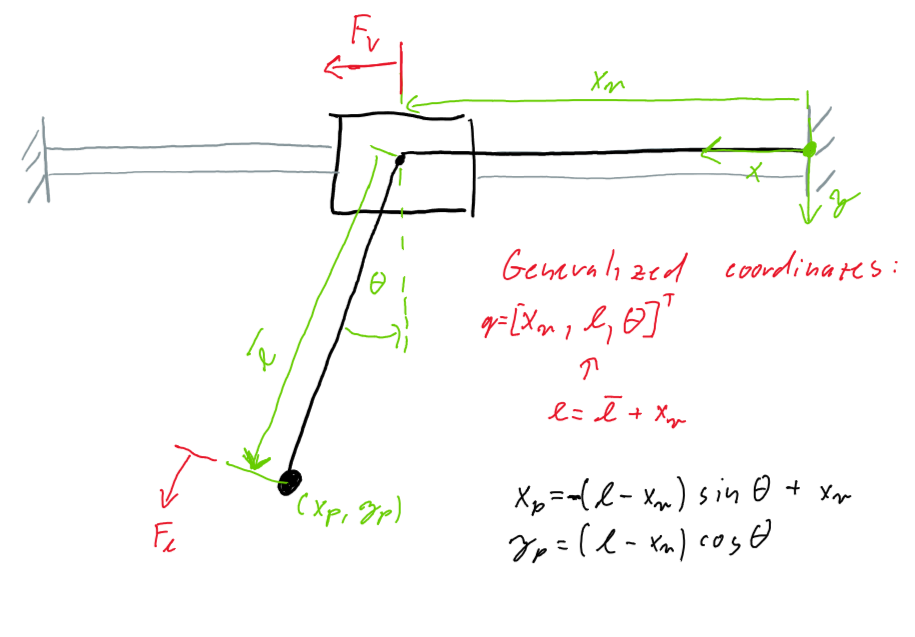

% Sampling time
Ts = 0.1;

% Number of states
n = 6;

% Number of control inputs
m = 2;

prms = [0.3; 0.4; 0.1; 0.1; 0.1; 1; 1];
% continuous dynamics x_dot = f_c(x, u)
% x = [p, Dp, l Dl, th, Dth]
%  xv   - position of the cart
%  Dxv  - velocity of the cart
%  l   - length of the rope
%  Dl  - time derivative of the length of the rope
%  th  - angluar position of the pen
%  Dth - angluar velocity of the pen
% u = [Fv, Fl]
%  Fv - force acting on the cart
%  Fl - force shortening/lengtening the rope
f_c = @(x, u) dynPlotter_ode(x, u, prms);

% Function calculating the pen position based on the state vector
pen_pos = @(x)[-(x(3,:)-x(1,:)).*sin(x(5,:)) + x(1,:);
    (x(3,:)-x(1,:)).*cos(x(5,:))];

% Cost function - penalize the control signal and the difference of the pen position from the
% given reference position
rs = @(x, u, x_ref, u_ref) [pen_pos(x) - x_ref(1:2); 0.01*(u-u_ref)];
Vs = @(x, u, x_ref, u_ref) 1/2*rs(x, u, x_ref, u_ref)'*rs(x, u, x_ref, u_ref);

rNs = @(x, x_ref) pen_pos(x) - x_ref(1:2);
VNs = @(x, x_ref) 1/2*rNs(x, x_ref)'*rNs(x, x_ref);

% Constraints h(x,u)<=0
umax = [ 10;  10];
umin = [-10; -10];
hs = @(x,u) deal([u-umax,-u+umin]);
hNs = @(x) [];

Now, let's linearize the dynamics of the discrete-time model and compute the sensitivity matrices. For efficiency, we used algorithmic differentiation tool called CasADi which not only computes the derivatives but it also generators efficient C code evaluating the derivatives. Hence, to succesfully run this section, you need to [instal CasADi](https://web.casadi.org/get/).

import casadi.*

% Fixed step Runge-Kutta 4 integrator
M = 1; % RK4 steps per interval
DT = Ts/M;
X0 = MX.sym('X', n);
U = MX.sym('U', m);
X = X0;
for j=1:M
    k1 = f_c(X, U);
    k2 = f_c(X + DT/2 * k1, U);
    k3 = f_c(X + DT/2 * k2, U);
    k4 = f_c(X + DT * k3, U);
    X=X+DT/6*(k1 +2*k2 +2*k3 +k4);
end

Hs = hs(X0, U);
Fs = Function('fs', {X0, U}, {X}, {'x0','u'}, {'X_next'});

As = Function('As', {X0, U}, {jacobian(X, X0)}, {'x0','u'}, {'A'});
Bs = Function('Bs', {X0, U}, {jacobian(X, U)}, {'x0','u'}, {'B'});
Cs = Function('Cs', {X0, U}, {jacobian(Hs, X0)}, {'x0','u'}, {'C'});
Ds = Function('Ds', {X0, U}, {jacobian(Hs, U)}, {'x0','u'}, {'D'});
HNs = Function('HNs', {X0}, {jacobian(hNs(X0), X0)}, {'x0'}, {'HN'});

X_ref = MX.sym('X_ref', n);
U_ref = MX.sym('U_ref', m);
dR_cost = [jacobian(rs(X0, U, X_ref, U_ref), X0) jacobian(rs(X0, U, X_ref, U_ref), U)]';
dRN_cost = jacobian(rNs(X0, X_ref), X0)';

Ws = Function('Ws', {X0, U, X_ref, U_ref}, {dR_cost*dR_cost'}, {'x','u', 'x_ref', 'u_ref'}, {'W'});
WNs = Function('WNs', {X0, X_ref}, {dRN_cost*dRN_cost'}, {'x','x_ref'}, {'WN'});
Js = Function('Js', {X0, U, X_ref, U_ref}, {[gradient(Vs(X0, U, X_ref, U_ref), X0); gradient(Vs(X0, U, X_ref, U_ref), U)]}, {'x','u', 'x_ref', 'u_ref'}, {'J'});
JNs = Function('JNs', {X0, X_ref}, {gradient(VNs(X0, X_ref), X0)}, {'x','x_ref'}, {'JN'});

C = CodeGenerator('jacAandB.c', struct('main', true, 'mex', true));
C.add(Fs);
C.add(As);
C.add(Bs);
C.add(Cs);
C.add(Ds);
C.add(HNs);
C.add(Ws);
C.add(WNs);
C.add(Js);
C.add(JNs);
C.generate();

mex jacAandB.c;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


fs = @(x, u) jacAandB('fs', x, u);
As = @(x, u) jacAandB('As', x, u);
Bs = @(x, u) jacAandB('Bs', x, u);
Cs = @(x, u) jacAandB('Cs', x, u);
Ds = @(x, u) jacAandB('Ds', x, u);
HNs = @(x) jacAandB('HNs', x);
Ws = @(x, u, xref, uref) jacAandB('Ws', x, u, xref, uref);
WNs = @(x, xref) jacAandB('WNs', x, xref);
Js = @(x, u, xref, uref) jacAandB('Js', x, u, xref, uref);
JNs = @(x, xref) jacAandB('JNs', x, xref);

Specify the parametrs of the simulation:

Tp = 2;           % Prediction Horizon
N = round(Tp/Ts); % Number of time steps in the prediction horizon

x0 = [1;0;2;0;0;0];
u0 = [prms(2)*9.81; -prms(2)*9.81];

Tf = 8+Tp;        % Final time
t = 0:Ts:Tf;      % time vector

Generate the reference:

x_ref = repmat(x0, 1, numel(t)+N);

x_ref(1, :) = 1;
x_ref(2, :) = 1;

t_tmp = 0:Ts:2;
I_start = round((Tp+0.5)/Ts);
I_end = I_start + numel(t_tmp)-1;
x_ref(1, I_start:I_end) = linspace(1, -1, numel(t_tmp));
x_ref(2, I_start:I_end) = 1 + 0.4*sin(2*pi/2*t_tmp);

t_tmp = 0:Ts:4;
I_start = round((Tp+0.5)/Ts);
I_end = I_start + numel(t_tmp)-1;

x_ref(1, I_start:I_end) = cos(2*pi/4*t_tmp);
x_ref(2, I_start:I_end) = 1 + 0.4*sin(2*2*pi/4*t_tmp);

x_ref(1, I_end+1:end) = x_ref(1, I_end);
x_ref(2, I_end+1:end) = x_ref(2, I_end);

u_ref = repmat(u0, 1, numel(t)+N);

Initialize the vectors where the simulation results will be stored:

x = zeros(n, numel(t));
u = zeros(m, numel(t));
x(:,1) = x0;

Initialize the solution trajectories:

% Initialize the guess trajectories
x_sol = repmat(x0, 1, N+1);
u_sol = zeros(m, N);

Initialize the plots:

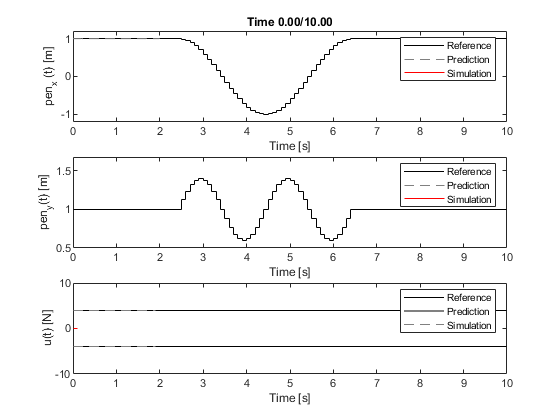

figure(1)
clf
set(gcf,'Visible','on')
subplot(311)
stairs(t, x_ref(1,1:numel(t)), 'k-')
hold on
f_penx_sol = plot(t(1:N+1), x_sol(1,:), '--', 'Color', 0.5*[1 1 1]);
f_penx_sim = plot(t(1), x0(1), 'r');
hold off
f_title_time = title(sprintf('Time %4.2f/%4.2f', t(1), t(end)));
xlabel('Time [s]')
ylabel('pen_x (t) [m]')
legend('Reference', 'Prediction', 'Simulation')
ylim([1.2*min(x_ref(1,:)) 1.2*max(x_ref(1,:))])

subplot(312)
stairs(t, x_ref(2,1:numel(t)), 'k-')
hold on
f_peny_sol = plot(t(1:N+1), x_sol(2,:), '--', 'Color', 0.5*[1 1 1]);
f_peny_sim = plot(t(1), x0(3), 'r');
hold off
xlabel('Time [s]')
ylabel('pen_y(t) [m]')
legend('Reference', 'Prediction', 'Simulation')
ylim([min(x_ref(2,:))-0.1 1.2*max(x_ref(2,:))])

subplot(313)
stairs(t', u_ref(:,1:numel(t))', 'k-');
hold on
f_u_sol = stairs(t(1:N)', u_sol', '--', 'Color', 0.5*[1 1 1]);
f_u_sim = stairs(t(1:2), zeros(m,2), 'r');
hold off
xlabel('Time [s]')
ylabel('u(t) [N]')
legend('Reference', 'Prediction', 'Simulation')
ylim([umin(1) umax(1)])

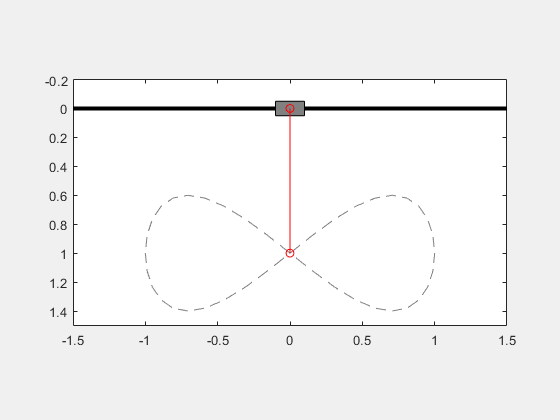


figure(2)
clf
set(gcf,'Visible','on')
pole_length = 1;
cart_vertices(:,1) = [-1; 1; 1; -1]*100e-3;
cart_vertices(:,2) = [-0.5; -0.5; 0.5; 0.5]*100e-3;
plot([-10 10], [0 0], 'k', 'LineWidth', 3)
hold on;
plot(x_ref(1,:), x_ref(2,:), '--k', 'Color', 0.5*[1 1 1])
h_simul_traj = plot(0, 0);
h_cart = fill(cart_vertices(:,1), cart_vertices(:,2), [.5 .5 .5]);
h_pole = plot([0,0, 0, 0],[0,0,0,pole_length],'ro-');
hold off;
axis equal;
axis([-1.5, 1.5, -.2, 1.5]);
set(gca, 'YDir', 'reverse');

Run the simulation with a simulated disturbance at time 4.0 s.

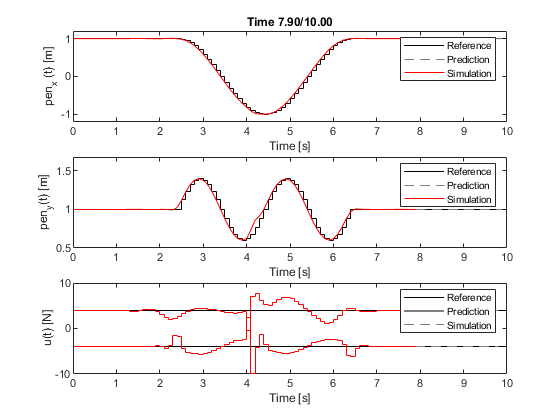

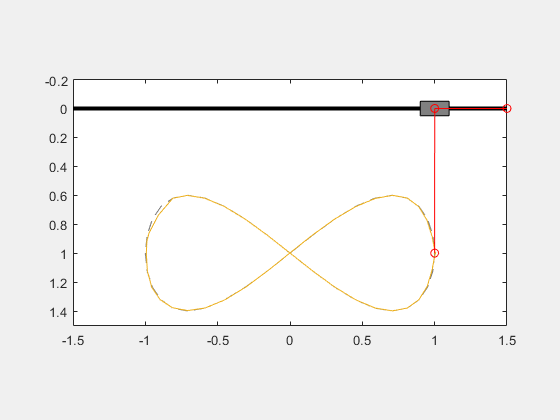

for i = 1:(numel(t)-1-N)
    % Shift the solution trajectories from the previous control period to obtain
    % the guess trajectories
    u_guess = [u_sol(:,2:end) u_sol(:,end)];
    x_guess = [x_sol(:,2:end) fs(x_sol(:,end), u_guess(:,end))];
    
    % Compute the sensitivities (matrices Ak, Bk, Ck, Dk, ...)
    [WN, JN, W, J, A, B, r, C, D, h, HN, hN] = computeSensitivities(x_guess, u_guess, x_ref(:, i:(i+N)), u_ref(:, i:(i+N-1)), Ws, WNs, Js, JNs, fs, As, Bs, hs, Cs, Ds, hNs, HNs);
    % Formulate the QP
    [Hbar, gbar, Abar, b0bar, Mbar, mbar] = LTV_MPC_to_QP(x(:,i), x_guess, WN, JN, W, J, A, B, r, C, D, h, HN, hN);
    % Solve the QP
    z_sol = quadprog(Hbar, gbar, Mbar, mbar, Abar, b0bar, [], [], [], optimoptions('quadprog', 'Display', 'off'));
    % Extract u_t from the output of the quadprog. The output contains
    % [dx_t; du_t; ...; dx_{t+N-1}; du_{t+N-2}; dx_{t+N}].
    
    z_sol_tmp = reshape(z_sol(1:end-n), n+m, N);
    
    dx_pred = [z_sol_tmp(1:n, :) z_sol(end-n+1:end)];
    du_pred = z_sol_tmp(n+1:n+m,:);
    
    % Current estimate of the optimal control and state trajectories
    x_sol = x_guess + dx_pred;
    u_sol = u_guess + du_pred;
    
    % The control input to be applied
    u(:,i) = u_sol(:,1);
    
    if t(i) == 4.0
        u(:,i) = u(:,i) + 20*rand(2,1)-10;
    end
    
    % Simulate the response of the system
    [~, x_new] =ode45(@(t, x_placeholder) f_c(x_placeholder, u(:,i)), [0 Ts], x(:,i));

    x(:,i+1) = x_new(end,:)';
    
    % Update the plots
    pen_sol = pen_pos(x_sol); 
    pen = pen_pos(x(:, 1:numel(t)));
    
    f_title_time.String = sprintf('Time %4.2f/%4.2f', t(i), t(end));
    
    f_penx_sol.XData = t(i:(i+N));
    f_penx_sol.YData = pen_sol(1,:);
    f_penx_sim.XData = t(1:i);
    f_penx_sim.YData = pen(1,1:i);
    
    f_peny_sol.XData = t(i:(i+N));
    f_peny_sol.YData = pen_sol(2,:);
    f_peny_sim.XData = t(1:i);
    f_peny_sim.YData = pen(2,1:i);
    
    for j=1:m
        f_u_sol(j).XData = t(i:(i+N-1));
        f_u_sol(j).YData = u_sol(j, :);
        f_u_sim(j).XData = t(1:i);
        f_u_sim(j).YData = u(j, 1:i);
    end
    
    pen = pen_pos(x(:, 1:numel(t))); 
    
    h_cart.Vertices(:,1) = cart_vertices(:,1) + x(1,i);
    h_pole.XData = [1.5; x(1,i); pen(1,i)];
    h_pole.YData = [0; 0; pen(2,i)];
    h_simul_traj.XData = pen(1,1:i);
    h_simul_traj.YData = pen(2,1:i);
    
    drawnow
    end